**Defining the Variables**

T_0 = 90;
dT_0 = -17.5;
T_a = 20;
k = 0.25;
A = [-k, 0; 0, -k]; 
t_max = 20;

**Plotting the Function Models**

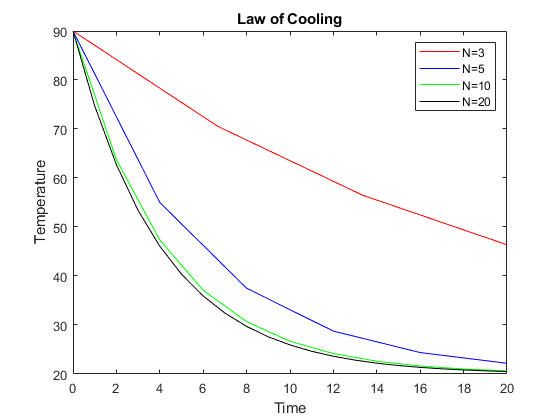

[x_axis_3 ,IEM_Model3] = IEMsolver(A,T_0,dT_0,t_max,3);
[x_axis_5, IEM_Model5] = IEMsolver(A,T_0,dT_0,t_max,5);
[x_axis_10,IEM_Model10] = IEMsolver(A,T_0,dT_0,t_max,10);
[x_axis_20, IEM_Model20] = IEMsolver(A,T_0,dT_0,t_max,20);
plot(x_axis_3 ,IEM_Model3,"r")
hold on
plot(x_axis_5 ,IEM_Model5,"b")
plot(x_axis_10 ,IEM_Model10,"g")
plot(x_axis_20,IEM_Model20,"k")
hold off
ylabel("Temperature")
xlabel("Time")
title("Law of Cooling")
legend("N=3","N=5","N=10","N=20")

**Finding Time where Temperature is 40**

Desired_Time = interp1(IEM_Model20, x_axis_20, 40)

Desired_Time =    5.083626009077551


Based on the graph of all the models, the best choice for time steps with reasonable accuracy would be N =10 as it strong matches N = 20 at a much lower computational cost.

The time at which the temperature is 40C is found graphically to be approx. 5.083626 minutes.